%https://www.mathworks.com/help/matlab/ref/fft.html

%variables
%Fs = 1000; % Sampling frequency                  
%T = 1/Fs;                    
%L = 8000; % signal length
%t = (0:L-1)*T; % Time
%t= 0:0.001:8

T=8

T = 8

F=4096

F = 4096

v_t = abs(sin(pi*t)) + 2*sin(3*pi*t) + 3*sin(6*pi*t)

v_t =          0    0.0192    0.0383    0.0575    0.0767    0.0959    0.1150    0.1342    0.1534    0.1725    0.1917    0.2109    0.2300    0.2492    0.2683    0.2874    0.3066    0.3257    0.3448    0.3640    0.3831    0.4022    0.4213    0.4404    0.4595    0.4785    0.4976    0.5167    0.5357    0.5548    0.5738    0.5928    0.6119    0.6309    0.6499    0.6689    0.6878    0.7068    0.7257    0.7447    0.7636    0.7825    0.8014    0.8203    0.8392    0.8581    0.8769    0.8957    0.9146    0.9334


len=length(v_t)

len = 32769

f=linspace(-F/2,F/2,len)

f = 1.0e+03 *

   -2.0480   -2.0479   -2.0478   -2.0476   -2.0475   -2.0474   -2.0473   -2.0471   -2.0470   -2.0469   -2.0467   -2.0466   -2.0465   -2.0464   -2.0463   -2.0461   -2.0460   -2.0459   -2.0457   -2.0456   -2.0455   -2.0454   -2.0452   -2.0451   -2.0450   -2.0449   -2.0448   -2.0446   -2.0445   -2.0444   -2.0442   -2.0441   -2.0440   -2.0439   -2.0438   -2.0436   -2.0435   -2.0434   -2.0433   -2.0431   -2.0430   -2.0429   -2.0427   -2.0426   -2.0425   -2.0424   -2.0423   -2.0421   -2.0420   -2.0419


t=0:1/F:T

t =          0    0.0002    0.0005    0.0007    0.0010    0.0012    0.0015    0.0017    0.0020    0.0022    0.0024    0.0027    0.0029    0.0032    0.0034    0.0037    0.0039    0.0042    0.0044    0.0046    0.0049    0.0051    0.0054    0.0056    0.0059    0.0061    0.0063    0.0066    0.0068    0.0071    0.0073    0.0076    0.0078    0.0081    0.0083    0.0085    0.0088    0.0090    0.0093    0.0095    0.0098    0.0100    0.0103    0.0105    0.0107    0.0110    0.0112    0.0115    0.0117    0.0120


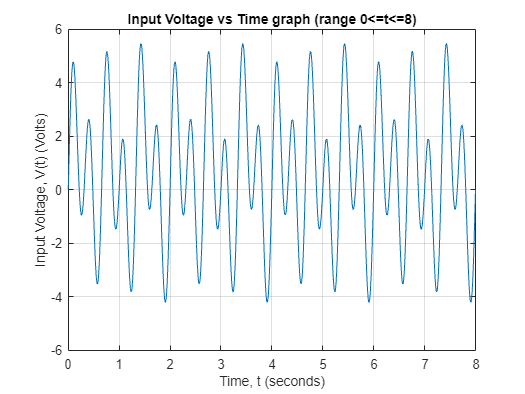



%Task i) plotting v(t)

plot(t,v_t)
xlabel('Time, t (seconds)')
ylabel('Input Voltage, V(t) (Volts)')
grid on
title('Input Voltage vs Time graph (range 0<=t<=8)')


%task ii) plot amplitude-frequency response of v(t)

v_f = fft(v_t) %fast fourier transform

v_f = 1.0e+04 *

   2.0861 + 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0001i  -0.0001 - 0.0001i  -0.0001 - 0.0001i  -0.0001 - 0.0002i  -0.0001 - 0.0002i  -0.0002 - 0.0003i  -0.6954 - 0.0009i   0.0001 - 0.0005i   0.0000 - 0.0007i   0.0000 - 0.0013i   0.0038 - 3.2770i  -0.0000 + 0.0010i  -0.0000 + 0.0004i  -0.0001 + 0.0001i  -0.1391 - 0.0002i   0.0001 - 0.0001i   0.0000 - 0.0003i   0.0000 - 0.0004i   0.0000 - 0.0006i  -0.0000 - 0.0010i  -0.0000 - 0.0016i  -0.0000 - 0.0034i  -0.0483 - 4.9153i   0.0000 + 0.0038i   0.0000 + 0.0020i   0.0000 + 0.0014i  -0.0000 + 0.0011i  -0.0000 + 0.0009i  -0.0000 + 0.0008i  -0.0000 + 0.0007i  -0.0331 + 0.0005i   0.0000 + 0.0005i   0.0000 + 0.0005i   0.0000 + 0.0005i  -0.0000 + 0.0004i  -0.0000 + 0.0004i  -0.0000 + 0.0004i  -0.0000 + 0.0004i  -0.0211 + 0.0003i   0.0000 + 0.0003i   0.0000 + 0.0003i   0.0000 + 0.0003i  -0.0000 + 0.0003i  -0.0000 + 0.0003i  -0.0000 + 0.0003i  -0.0000 + 0.0003i  -0.0146 + 0.0002i   0.0000 + 0.0002i


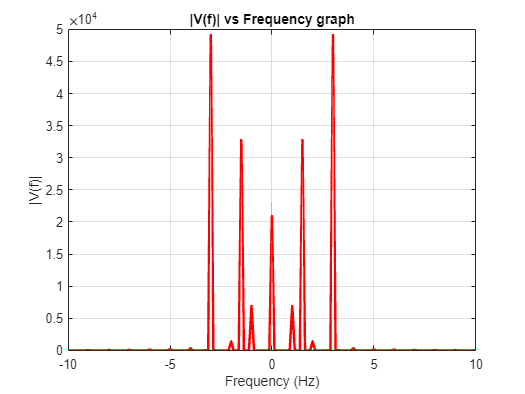


%plot((-L/2:(L/2-1))*Fs/(L-1),fftshift(abs(v_f)),"LineWidth",2) %vectors of same length
plot(f,fftshift(abs(v_f)),'r',"LineWidth",2)
xlabel('Frequency (Hz)')
ylabel('|V(f)|')
grid on
title('|V(f)| vs Frequency graph')
xlim([-10 10]) %limiting x axis to make data readable



%task iii) plot amplitude-frequency response of circuit

%Start
s=1j*2*pi*f

s = 1.0e+04 *

   0.0000 - 1.2868i   0.0000 - 1.2867i   0.0000 - 1.2866i   0.0000 - 1.2866i   0.0000 - 1.2865i   0.0000 - 1.2864i   0.0000 - 1.2863i   0.0000 - 1.2862i   0.0000 - 1.2862i   0.0000 - 1.2861i   0.0000 - 1.2860i   0.0000 - 1.2859i   0.0000 - 1.2859i   0.0000 - 1.2858i   0.0000 - 1.2857i   0.0000 - 1.2856i   0.0000 - 1.2855i   0.0000 - 1.2855i   0.0000 - 1.2854i   0.0000 - 1.2853i   0.0000 - 1.2852i   0.0000 - 1.2851i   0.0000 - 1.2851i   0.0000 - 1.2850i   0.0000 - 1.2849i   0.0000 - 1.2848i   0.0000 - 1.2848i   0.0000 - 1.2847i   0.0000 - 1.2846i   0.0000 - 1.2845i   0.0000 - 1.2844i   0.0000 - 1.2844i   0.0000 - 1.2843i   0.0000 - 1.2842i   0.0000 - 1.2841i   0.0000 - 1.2840i   0.0000 - 1.2840i   0.0000 - 1.2839i   0.0000 - 1.2838i   0.0000 - 1.2837i   0.0000 - 1.2837i   0.0000 - 1.2836i   0.0000 - 1.2835i   0.0000 - 1.2834i   0.0000 - 1.2833i   0.0000 - 1.2833i   0.0000 - 1.2832i   0.0000 - 1.2831i   0.0000 - 1.2830i   0.0000 - 1.2829i


RS=1

RS = 1

RP=2

RP = 2

L=0.1*s

L = 1.0e+03 *

   0.0000 - 1.2868i   0.0000 - 1.2867i   0.0000 - 1.2866i   0.0000 - 1.2866i   0.0000 - 1.2865i   0.0000 - 1.2864i   0.0000 - 1.2863i   0.0000 - 1.2862i   0.0000 - 1.2862i   0.0000 - 1.2861i   0.0000 - 1.2860i   0.0000 - 1.2859i   0.0000 - 1.2859i   0.0000 - 1.2858i   0.0000 - 1.2857i   0.0000 - 1.2856i   0.0000 - 1.2855i   0.0000 - 1.2855i   0.0000 - 1.2854i   0.0000 - 1.2853i   0.0000 - 1.2852i   0.0000 - 1.2851i   0.0000 - 1.2851i   0.0000 - 1.2850i   0.0000 - 1.2849i   0.0000 - 1.2848i   0.0000 - 1.2848i   0.0000 - 1.2847i   0.0000 - 1.2846i   0.0000 - 1.2845i   0.0000 - 1.2844i   0.0000 - 1.2844i   0.0000 - 1.2843i   0.0000 - 1.2842i   0.0000 - 1.2841i   0.0000 - 1.2840i   0.0000 - 1.2840i   0.0000 - 1.2839i   0.0000 - 1.2838i   0.0000 - 1.2837i   0.0000 - 1.2837i   0.0000 - 1.2836i   0.0000 - 1.2835i   0.0000 - 1.2834i   0.0000 - 1.2833i   0.0000 - 1.2833i   0.0000 - 1.2832i   0.0000 - 1.2831i   0.0000 - 1.2830i   0.0000 - 1.2829i


C=1/(s*(0.5))

Error using  / 
Matrix dimensions must agree.


%^ZP=1/((1/C)+(1/RP)
%End

f=linspace(0,10,1000)
H=tf(2, 0.4*pi^2*f+2.2*1j*pi*f+3)


bodemag(circuit)
grid on
xlim([-10 10])

%task iv) plot v,oltage accross R2 (t=0 to t=infty)

syms t s

v_t=abs(sin(pi*t)) + 2*sin(3*pi*t) + 3*sin(6*pi*t)
V_s=laplace(v_t)

H_s=2./0.1*s^2+1.1*s+3

h_t=ilaplace(H)
H_f=fft(h_t)

Y_f=H_f*v_f
y_t=ifft(Y_f)

fplot(y_t)

%lsim(circuit, v_t, t)
%xlim([0 8])

%task iv) plot voltage accross R2 (t=0 to t=4, then stops)
%v_t_0to4 = v_t.*heaviside(t) - v_t.*heaviside(t-4)
%lsim(circuit, v_t_0to4,t)
%xlim([0 8])